## Punto 3

### Sistema de ¼ de la suspensión de un bus

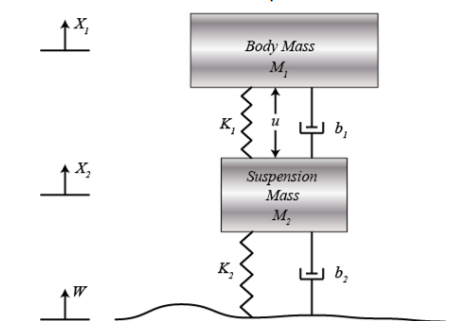

A partir de la imagen anterior y de la ley de Newton, podemos obtener las ecuaciones dinámicas siguientes:

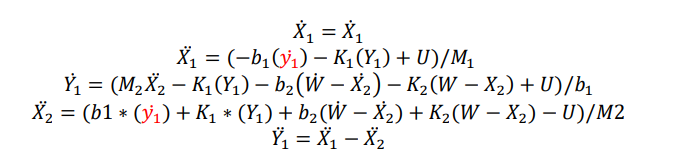

**NOTA:** Diferenciar en MATLAB entre 𝑌1 ̇ & 𝑦1 ̇ 

    **a.** Encuentre el espacio de estados del sistema teniendo como estados 𝑋1 ,𝑋1 ̇ , 𝑌1 𝑦 𝑌1 ̇ 

    **b.** A partir del espacio de estados encuentre la función de transferencia de 𝑌1(𝑠)/𝑈(𝑠)

### a. Espacio de Estados

clear all
clc
% Variables Simbólicas
syms  b1 b2 x1 x2 k1 k2 M1 M2 U w dx1 v2 v1 dx2 dw dy1 Y1

d2x1=(-b1*(dy1)-k1*(Y1)+U)/M1;
d2x2=(b1*(dy1)+k1*(Y1)+b2*(dw-dx2)+k2*(w-x2)-U)/M2;
dY1=(M2*d2x2-k1*(Y1)-b2*(dw-dx2)-k2*(w-x2)+U)/b1;
d2Y1= d2x1-d2x2;

### Variables de estado  

%X=  %vector variables de estado
%U= %vector de entradas
%Y= %vector de salida

### Jacobianos

dX=[dx1,d2x1,dY1,d2Y1] %derivadas de las variables de estado

$$dX = \left(\begin{array}{cccc} {\mathrm{dx}}_{1} & -\frac{Y_{1}\,k_{1}-U+b_{1}\,{\mathrm{dy}}_{1}}{M_{1}} & {\mathrm{dy}}_{1} & -\frac{Y_{1}\,k_{1}-U+b_{1}\,{\mathrm{dy}}_{1}+b_{2}\,\left(\mathrm{dw}-{\mathrm{dx}}_{2}\right)+k_{2}\,\left(w-x_{2}\right)}{M_{2}}-\frac{Y_{1}\,k_{1}-U+b_{1}\,{\mathrm{dy}}_{1}}{M_{1}} \end{array}\right)$$

X=[x1,dx1,Y1,dY1]  %vector variables de estado

$$X = \left(\begin{array}{cccc} x_{1} & {\mathrm{dx}}_{1} & Y_{1} & {\mathrm{dy}}_{1} \end{array}\right)$$

Y=[x1-x2]  %vector de salida

$$Y = x_{1}-x_{2}$$



Am = jacobian(dX,X)  % Calcula el coef A 

$$Am = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{k_{1}}{M_{1}} & -\frac{b_{1}}{M_{1}}\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{k_{1}}{M_{1}}-\frac{k_{1}}{M_{2}} & -\frac{b_{1}}{M_{1}}-\frac{b_{1}}{M_{2}} \end{array}\right)$$

Bm = jacobian(dX,U)  % Calcula el coef B 

$$Bm = \left(\begin{array}{c} 0\\ \frac{1}{M_{1}}\\ 0\\ \frac{1}{M_{1}}+\frac{1}{M_{2}} \end{array}\right)$$

Cm = jacobian(Y,X)   % Calcula el coef C 

$$Cm = \left(\begin{array}{cccc} 1 & 0 & 0 & 0 \end{array}\right)$$

Dm = jacobian(Y,U)   % Calcula el coef D

$$Dm = 0$$

### b. Función de Transferencia

% Función de transferencia
syms s

SI = s*eye(4); 
Gs = Cm*((SI - Am)^(-1))*Bm + Dm;
Gs=simplify(Gs)

$$Gs = \frac{M_{2}}{M_{1}\,k_{1}+M_{2}\,k_{1}+M_{1}\,b_{1}\,s+M_{2}\,b_{1}\,s+M_{1}\,M_{2}\,s^{2}}$$


% Asignando valores arbitrarios a las variables
b1 = 3;
b2 = 3;
M1 = 2;
M2 = 4;
k1 = 2;
k2 = 2;

s=tf('s');
G3 = M2/(k1*M1 + k1*M2 + M1*b1*s + M2*b1*s + M1*M2*s^2)

G3 =
 
          4
  -----------------
  8 s^2 + 18 s + 12
 
Continuous-time transfer function.
Model Properties


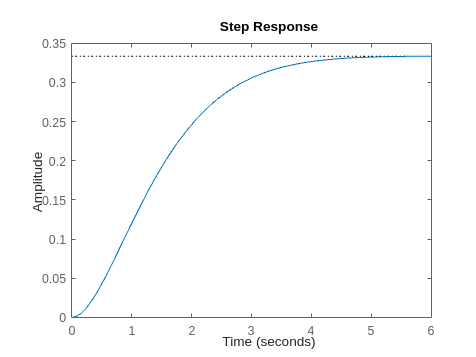


% Graficamos la función de transferencia
step(G3)